#                        TRABAJO PRÁCTICO 2

#                 PROCESAMIENTO MULTIRATE

#### Alumno: Brian Alex Fuentes Acuña.

#### Padron: 101785 

### **1. Introducción **

### **1.1. Objetivo **

**Dado el problema planteado en el Trabajo Práctico 1, considere una señal de audio digitalizada a una frecuencia de muestreo de fs = 44100 Hz, la cual se ve afectada por tres interferencias de banda angosta. Se requiere nuevamente procesar la señal de audio contaminada implementando un filtro FIR digital de Fase Lineal Generalizada de alta selectividad. En este caso, el principal objetivo es la implementación del filtro mediante las técnicas multirate para reducir los recursos computacionales garantizando el mismo desempeño que el filtro original. En la siguiente figura se ve un esquema general del diseño propuesto para lograr el objetivo:**

      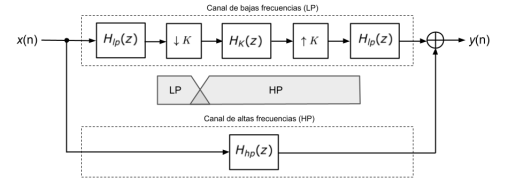

*Figura 1: Implementación eficiente para un cancelador de interferencias en bajas frecuencias.* 

**Como se observa, el sistema divide el espectro de la señal en una banda de bajas frecuencias y otra de altas (de forma no simétrica). La parte de altas (HP) debe preservarse sin modificaciones, ya que no requiere procesamiento adicional, mientras que la parte de bajas (LP) debe someterse a la eliminación de interferencias y hacerlo de forma eficiente.**

**1.2. Datos suministrados **

**Fuente de sonido: **

**Para probar subjetivamente los resultados del filtrado, utilice las mismas pistas de audio disponibles en el campus que fueran utilizadas para el Trabajo Práctico 1. **

**Interferencias: **

**Considere las interferencias en el archivo interferencias2.wav, la cual posee tres tonos mezclados de frecuencias f1 = 300 Hz, f2 = 500 Hz y f3 = 700 Hz (fs = 44100 Hz). IMPORTANTE: éstas interferencias son diferentes a las del trabajo anterior. Tenga en cuenta que en este caso las frecuencias son más bajas, lo que introduce el inconveniente de requerir una selectividad mucho mayor, traduci´endose esto en la necesidad de un filtro con un orden considerablemente alto.**

**Filtros:**

**Para enfocarnos principalmente en el diseño multirate, se dispone de casi todos los filtros requeridos para cada etapa del sistema. Estos se encuentran en el archivo **`filtros tp2.mat`**. El mismo contiene: filtro supresor de interferencias sin optimizar (h), filtro pasa bajos para decimación e interpolación (**`h_lp`**) y filtro pasa altos (**`h_hp`**). **

### 2. Desarrollo 

### Problema 1 

**En este problema se explora el filtro supresor de interferencias que no posee ningún tipo de optimización en cuanto a su eficiencia computacional. **

clc; clear; close all;
f1 = 300;   %Hz 
f2 = 500;   %Hz 
f3 = 700;   %Hz 
fs = 44100; %Hz

filtros = load('filtros_tp2.mat');
%Se cargan los fitros al workspace explicitamente.
% filtro supresor de interferencias sin optimizar (h)
h = filtros.h;
% filtro pasa bajos para decimación e interpolación (h_lp).
h_lp = filtros.h_lp;
%filtro pasa altos (h_hp).
h_hp = filtros.h_hp;

**(a) **

**Del archivo que contiene los filtros, utilice el filtro h. Grafique su respuesta impulsiva h(n), su respuesta en frecuencia |H(ω)| y diagrama de polos y ceros. Analice algunas de sus características como ancho de banda de cada supresor de frecuencias, ripples en las bandas de paso y supresión, orden y tipo FLG.**

%genero los puntos nfft y mi eje de precuencias.
nfft = 1e6; %length()
w = linspace(0, 2*pi, nfft);

Procedo a graficar mi respuesta impuslvida y en frecuencia para estudiar el filtro $h$ que se nos da :

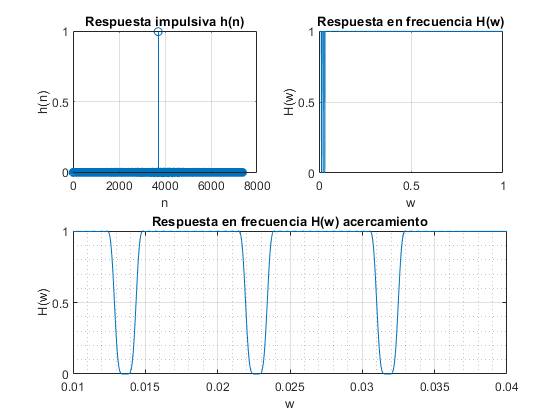

H = fft(h, nfft);

figure()
subplot(2, 2, 1)
    stem(h)
    xlabel("n")
    ylabel("h(n)")
    title("Respuesta impulsiva h(n)")
    grid on
    
subplot(2, 2, 2)
    plot(w/pi, abs(H) )
    xlim([0, 1])
    ylabel("H(w)")
    xlabel("w")
    title("Respuesta en frecuencia H(w)")
    grid on
    
subplot(2, 2, [3, 4])
    p_H = plot(w/pi, (abs(H) ));
    xlim([0.01, 0.04])
    ylabel("H(w)")
    xlabel("w")
    title("Respuesta en frecuencia H(w) acercamiento")
    grid on
    grid minor

Tambien se grafica el diagrama de polos y ceros para comprender mejor el tipo de FLG que es:

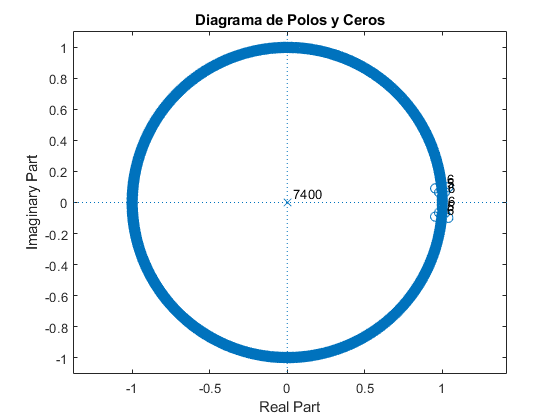

    
figure()
    zplane(h, 1)
    title("Diagrama de Polos y Ceros")

El orden del filtro es de $7401$ es un filtro de orden par (N impar)  y por su respuesta al impuslo se sabe que es simetrica, entonces un filtro de $tipo I$, esto se puede confirmar observando el diagrama de polos y ceros en donde se ve con el  y  no se encuentran ceros.

Luego se procede a obtener las características de diseño de este filtro para utilizarlas en los próximos ejercicios.

Para ello se tomarán los ripples de las bandas de paso y transición de la respuesta en frecuencia de 

hay que tener en cuenta de tomar el mayor ripple de las bandas de pasos y transición, es decir el peor caso.

tomar los anchos de banda de transición y elegir el máximo, dado que por simplicidad se dirá que los distintos notchs presentes en el filtro son los mismos pero corridos en frecuencia.

También el ancho de banda de rechazo debe ser el máximo que se encuentre, aunque dieron casi iguales.

%El orden es
M = length(h)  %7401(impar) con sin ceros en z=1, z=-1, es TIPO 1.

M = 7401

deltaP1 = 0.003;     %aprox
deltaS1 = 0.0001344;  %aprox

deltaP2 = 0.003;     %aprox
deltaS2 = 0.0001696; %aprox

deltaP3 = 0.003;    %aprox
deltaS3 = 0.0001609;  %aprox

deltaP = max([deltaP1, deltaP2, deltaP3])

deltaP = 0.0030

deltaS = max([deltaS1, deltaS2, deltaS3])

deltaS = 1.6960e-04


%--
wbp_1 = 0.01237;
wbs_1 = 0.01341;
was_1 = 0.0138;
wap_1 = 0.01484;

DW1 = max([abs(wbp_1 - wbs_1), abs(was_1 - wap_1)])

DW1 = 0.0010

DWs1 = abs(wbs_1 - was_1)

DWs1 = 3.9000e-04


wbp_2 = 0.02144;
wbs_2 = 0.02248;
was_2 = 0.02287;
wap_2 = 0.02391;

DW2 = max([abs(wbp_2 - wbs_2), abs(was_2 - wap_2)])

DW2 = 0.0010

DWs2 = abs(wbs_2 - was_2)

DWs2 = 3.9000e-04


wbp_3 = 0.03051;
wbs_3 = 0.03155;
was_3 = 0.03195;
wap_3 = 0.03297;

DW3 = max([abs(wbp_3 - wbs_3), abs(was_3 - wap_3)])

DW3 = 0.0010

DWs3 = abs(wbs_3 - was_3)

DWs3 = 4.0000e-04


%la banda de transicion mas restrictiva será:
DW = min([DW1, DW2, DW3]) *pi;      %[Rad/s]          %m u n p
disp("DW: "+DW/pi+"pi")

DW: 0.00104pi


DF = DW*fs/(2*pi);               %[Hz]
disp("DF: "+DW/pi+"Hz")

DF: 0.00104Hz


%La banda de rechazo es:
DWs = max([DWs1, DWs2, DWs3])*pi   %[Rad/s]

DWs = 0.0013

disp("DWs: "+DWs/pi+"pi")

DWs: 0.0004pi


Dfs = DWs*fs/(2*pi)             %[Hz]

Dfs = 8.8200

disp("Dfs: "+DW/pi+"Hz")

Dfs: 0.00104Hz


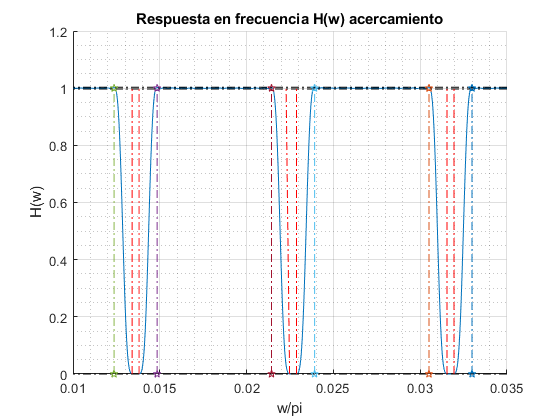


%Verificacion visual.
figure()
    hold on;
    plot(p_H.XData, p_H.YData) %ya esta normalizado a pi.
    %ripples
    plot([0 1], [1+deltaP, 1+deltaP], '-.k')
    plot([0 1], [1-deltaP, 1-deltaP], '-.k')  
    plot([0 1], [  deltaS,   deltaS], '-.k')
    
    %Banda de supresion
    plot([f1*2*pi/fs + DWs/2 , f1*2*pi/fs + DWs/2]./pi, [0 1], '-.r')
    plot([f1*2*pi/fs - DWs/2 , f1*2*pi/fs - DWs/2]./pi, [0 1], '-.r')
    
    plot([f2*2*pi/fs + DWs/2 , f2*2*pi/fs + DWs/2]./pi, [0 1], '-.r')
    plot([f2*2*pi/fs - DWs/2 , f2*2*pi/fs - DWs]./pi, [0 1], '-.r')
    
    plot([f3*2*pi/fs + DWs/2 , f3*2*pi/fs + DWs/2]./pi, [0 1], '-.r')
    plot([f3*2*pi/fs - DWs/2 , f3*2*pi/fs - DWs/2]./pi, [0 1], '-.r')
    
    %sumo la banda de transicion
    plot([f1*2*pi/fs + DWs/2+DW , f1*2*pi/fs + DWs/2+DW]./pi, [0 1], '-.p')
    plot([f1*2*pi/fs - DWs/2-DW , f1*2*pi/fs - DWs/2-DW]./pi, [0 1], '-.p')
    
    plot([f2*2*pi/fs + DWs/2+DW , f2*2*pi/fs + DWs/2+DW]./pi, [0 1], '-.p')
    plot([f2*2*pi/fs - DWs/2-DW , f2*2*pi/fs - DWs/2-DW]./pi, [0 1], '-.p')
    
    plot([f3*2*pi/fs + DWs/2+DW , f3*2*pi/fs + DWs/2+DW]./pi, [0 1], '-.p')
    plot([f3*2*pi/fs - DWs/2-DW , f3*2*pi/fs - DWs/2-DW]./pi, [0 1], '-.p')
    
    xlim([0.01, 0.035])
    ylabel("H(w)")
    xlabel("w/pi")
    title("Respuesta en frecuencia H(w) acercamiento")
    grid on
    grid minor

Observar la imagen en donde se pueden ver que los parametros obteniedos son correctos, estos son:


$$N = 7400$$



$$\delta_P = 0.003$$



$$\delta_S = 1.696x10^{-4}$$



$$\Delta W = 0.001 \pi [rad/S]$$



$$\Delta Ws = 0.0013 \pi [rad/S]$$


**(b) **

**Utilice la señal de interferencias y algunas de las pistas de audio para generar la señal contaminada. Aplique el filtro supresor y grafique el espectrograma de la señal contaminada x(n) y la salida del filtro y(n) luego de suprimir las interferencias. Verifique la utilidad del filtro subjetivamente reproduciendo las tres señales: contaminada, filtrada y original.**

addpath("C:\Users\brian\OneDrive\Escritorio\PrcSeñales1\2_Multirate\Tp2Multirrate\CANCIONES")
[S1, FS1] = audioread('Pista_01.wav');
[S2, FS2] = audioread('Pista_02.wav');
[S3, FS3] = audioread('Pista_03.wav');
[S4, FS4] = audioread('Pista_04.wav');
[S5, FS5] = audioread('Pista_05.wav');
[Sv, FSv] = audioread('interferencias2.wav');

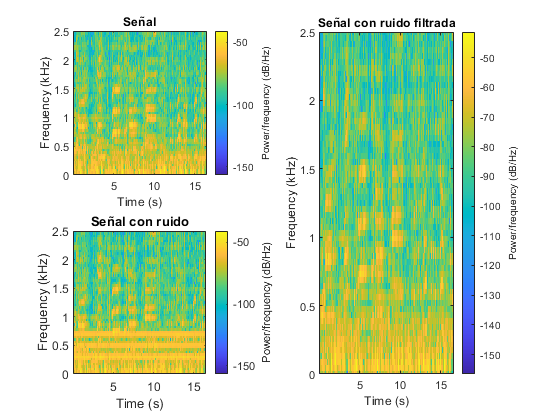

Fs = FSv;
%Señal contaminada
x1 = S1 + Sv;
%Señal luego del filtro supresor de interferencias.
xh1 = conv(x1, h);
plotSpectogram(S1, x1, xh1, Fs)

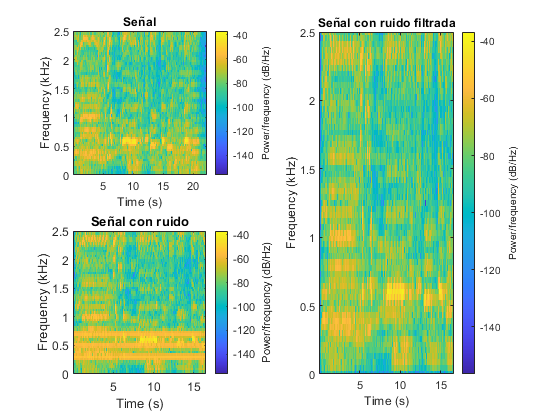


% %Señal contaminada
% x2 = S2(1:length(Sv)) + Sv;
% %Señal luego del filtro supresor de interferencias.
% xh2 = conv(x2, h);
% plotSpectogram(S2, x2, xh2, Fs)

%Señal contaminada
x3 = S3(1:length(Sv)) + Sv;
%Señal luego del filtro supresor de interferencias.
xh3 = conv(x3, h);
plotSpectogram(S3, x3, xh3, Fs)

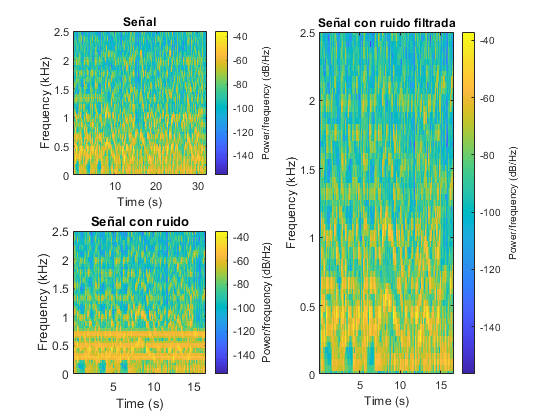


%Señal contaminada
x5 = S5(1:length(Sv)) + Sv;
%Señal luego del filtro supresor de interferencias.
xh5 = conv(x5, h);
plotSpectogram(S5, x5, xh5, Fs)

Se puede observar que en todos los casos (pista 1, 3 y 5) se filtran las 3 bandas de interferencia con bastante exito. 

En que la pista 3 tiene componentes de frecuencia de más peso en la misma banda que la interferencia de frecuencia más baja, por lo que el sonido es un poco mas afectado en este caso. Se escucharon las 3 pistas en sus 3 diferentes estados (con interferencia, filtrada y original) 

#### Problema 2 

**En este problema se busca implementar el filtro de forma eficiente a partir del esquema multirate de la figura 1. **

**(a) Considere los filtros Hlp(z) y Hhp(z) para separar las bandas en bajas y altas frecuencias, respectivamente. Para la parte de bajas, determine un factor de decimación K adecuado para que la banda LP se pueda procesar a la menor tasa de muestreo posible. **

Datos de los filtros h_lp y h_hp.

h_lp: $#h\_lp = 301$, $w_p = 0.04746 \pi$, $w_s = 0.0746 \pi$

h_hp: $#h\_hp =601$, $w_p = 0.07344. \pi$, $w_s = 0.0476 \pi$

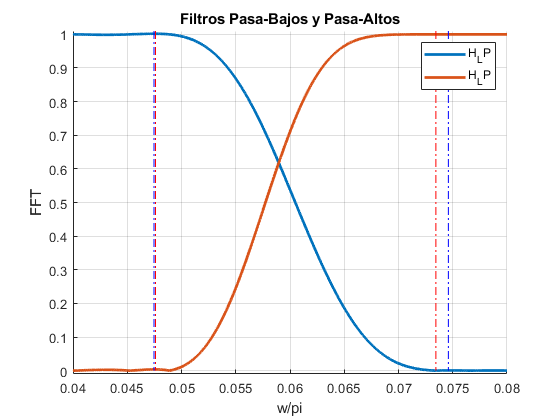

%h_lp = 301    h_hp = 601.
%[L,M]=rat(fs2/fs1),  donde L y M son los enteros m´as bajos que cumplen con la relaci´on
%L/M=fs2/fs1.
%Grafiquemos los filtros para comprender mejor no que se necesita.
wp_lp = 0.04746*pi; ws_lp = 0.0746*pi;
wp_hp = 0.07344*pi; ws_hp = 0.0476*pi;


H_LP = fft(h_lp, nfft);
H_HP = fft(h_hp, nfft);

figure()
    hold on;
    p_HLP= plot(w/pi, abs(H_LP), 'LineWidth', 2);
    p_HHP= plot(w/pi, abs(H_HP), 'LineWidth', 2);
    
    plot([ wp_lp/pi wp_lp/pi], [0 1.2], '-.b')
    plot([ ws_lp/pi ws_lp/pi], [0 1.2], '-.b')
    
    plot([ wp_hp/pi wp_hp/pi], [0 1.2], '-.r')
    plot([ ws_hp/pi ws_hp/pi], [0 1.2], '-.r')
    
    legend([p_HLP p_HHP], {'H_LP', 'H_LP'});
    
    grid on
    xlim([0.04 0.08])
    ylim([-0.01 1.01])
    xlabel("w/pi")
    ylabel("FFT")
    title("Filtros Pasa-Bajos y Pasa-Altos")

Entonces cuando se decima $w_s$-->$$w_{sk}=w_s/K < \pi/K$$ pero si se quiere menor cantidad de muestras entonces se tiene que admitir un filtro mas olgado, es decir con un ancho de banda de transcion mayor, el caso maximo es cuando $w_{sk} = \pi/K$ entonces sabiendo cuando vale $w_s = 0.0746 \pi$ $K = \pi / w_s \approx 13.4048$, $K = 14$.

K= 14;

**(b) **

**Para el factor de decimación hallado, diseñe un filtro **$h_k(n)$** con el método LS (firls()) que suprima las tres interferencias luego de la decimación. Para las especificaciones, tome como referencia el filtro original H(z), definiendo los mismas tolerancias para los ripples, pero con un ancho de banda K veces mayor y un orden apróximadamente K veces menor.**

Las frecuencias $f1, f2$ y $f3$ al decimar deben cambiar por lo que el filtro $h_k$ debe filtrar distintas frecuencias $f_1->f_1.K = 4200$, $f_2->f_2.K = 7000$ y $f_3->f_3.K = 9800$.

En general al decimar hay que multiplicar las frecuencias por $K$ va lo mismo para $\Delta W <- \Delta W.K$ y $\Delta W_s<-\Delta W_s.K$

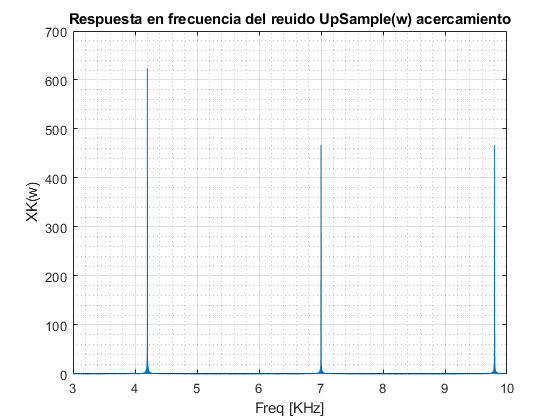

% pero con un ancho de banda K veces mayor 
% y un orden apróximadamente K veces menor
% f1 = 300;   %Hz 
% f2 = 500;   %Hz 
% f3 = 700;   %Hz 
% fs = 44100; %Hz
%Veamos cuales pueden ser mis anchos de banda.
xk = filter(h_lp, 1, Sv);
xk = downsample(xk, K);
F = ( (0 : 1/nfft : 1-1/nfft) * fs);
XK = fft(xk, nfft);

figure()
    plot(F*1e-3, (abs(XK) ))
    xlim([3, 10])
    ylabel("XK(w)")
    xlabel("Freq [KHz]")
    title("Respuesta en frecuencia del reuido UpSample(w) acercamiento")
    grid on
    grid minor


Df = 1e3*max([abs(4.199-4.201), abs(6.999-7.001), abs(9.799-9.801)]) %Hz

Df = 2.0000

%Corresponde al f1.K

El ancho de banda de supresion se tiene en cuenta el peor caso, pero fueron todos iguales donde $\Delta_f = 2 Hz$  y si se tiene en cuenta el ancho de banda de supresion del filtro $h$ es $\Delta_{F_s} = 2.81 Hz$ no parece haber relacion entre ambas, por ello para estar mas seguro se eleige un ancho de banda igual o superior a las obtenidas en ambos casos.

Por otra parte se pide un filtro con orden $K$ veces menor osea $7401/K \approx  529$ el cual se va ajustando hasta que que cumpla con las especificaciones, quedando finalmente $M = 530$ practicamente igual, incluso podria ser un poco menos pero los ripples quedaron incluso un poco por debajo.

El filtro tambien sera de  **tipo I**, por lo que debe ser *simetrico* y de *largo N impar (M par)*


%wc= pi/L;
%filtro original H(z), mismas tolerancias para los ripples,
%ancho de banda K veces mayor y un orden apróximadamente K veces menor.
DW = DW*K

DW = 0.0457

DWs = DWs*K

DWs = 0.0176

%Dws = 2*pi*Df/fs
w1k = K*f1*2*pi/fs;
w2k = K*f2*2*pi/fs;
w3k = K*f3*2*pi/fs;

w_upsample = [w1k w2k w3k];%K.*[f1, f2, f3].*(2*pi/fs);
M = 530%570

M = 530

N= M - 1

N = 529


%filtro de interpolacion
[F, A, R] = paramLS([DW DW DW], [DWs DWs DWs], deltaP, deltaS, w_upsample);

h_k = firls(N, F, A, 1./R);    %tiene un warning, nose ta loco

Nuevamente grafico los parámetros obtenidos para ver si se ajustan filtro, como se le en la siguiente imagen se ajustan bien

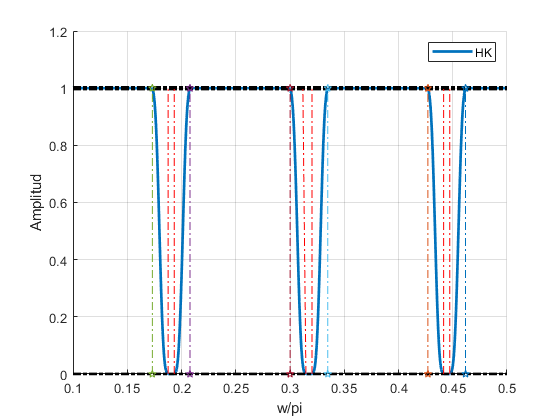

%Normalizo el filtro.
H_K = fft(h_k, nfft); %la dft me lo reescala en L

%hk = dowsample(h, K);
%h_down = downsample(h, K);
%H = fft(downsample(h, K), nfft);


figure()
    hold on;
    plot(w/pi, abs(H_K), 'LineWidth', 2)
    plot([0 1], [1 + deltaP, 1 + deltaP], '-.k', "LineWidth", 2)
    plot([0 1], [1 - deltaP, 1 - deltaP], '-.k', "LineWidth", 2)    
    plot([0 1], [    deltaS,     deltaS], '-.k', "LineWidth", 2)
    
    %Banda de supresion
    plot([w1k + DWs/2 , w1k + DWs/2]./pi, [0 1], '-.r')
    plot([w1k - DWs/2 , w1k - DWs/2]./pi, [0 1], '-.r')
    
    plot([w2k + DWs/2 , w2k + DWs/2]./pi, [0 1], '-.r')
    plot([w2k - DWs/2 , w2k - DWs]./pi, [0 1], '-.r')
    
    plot([w3k + DWs/2 , w3k + DWs/2]./pi, [0 1], '-.r')
    plot([w3k - DWs/2 , w3k - DWs/2]./pi, [0 1], '-.r')
    
    %sumo la banda de transicion
    plot([w1k + DWs/2+DW , w1k + DWs/2+DW]./pi, [0 1], '-.p')
    plot([w1k - DWs/2-DW , w1k - DWs/2-DW]./pi, [0 1], '-.p')
    
    plot([w2k + DWs/2+DW , w2k + DWs/2+DW]./pi, [0 1], '-.p')
    plot([w2k - DWs/2-DW , w2k - DWs/2-DW]./pi, [0 1], '-.p')
    
    plot([w3k + DWs/2+DW , w3k + DWs/2+DW]./pi, [0 1], '-.p')
    plot([w3k - DWs/2-DW , w3k - DWs/2-DW]./pi, [0 1], '-.p')
    
    grid on
    legend("HK")
    xlabel("w/pi")
    ylabel("Amplitud")
    xlim([0.1 0.5])

**(c) **

**Implemente la cadena completa del canal LP. Para ello aplique como entrada una señal impulsiva. Grafique la respuesta en frecuencia de la salida total del canal LP y compare el filtro en la región de bajas frecuencias contra la salida del filtro original aplicando la misma entrada impulsiva. Observe las diferencias en las bandas suprimidas y si no se ajustan a lo esperado, retoque el diseño hasta mejorar la respuesta.**

Luego hay que implementar la cadena LP(la que está arriba) esto es simplemente convolucionando la señal  con los filtros y submuestrear o sobremuestrear según sea el caso, el largo de la señal de entrada será de largo 8000 para ver mejor la respuesta 

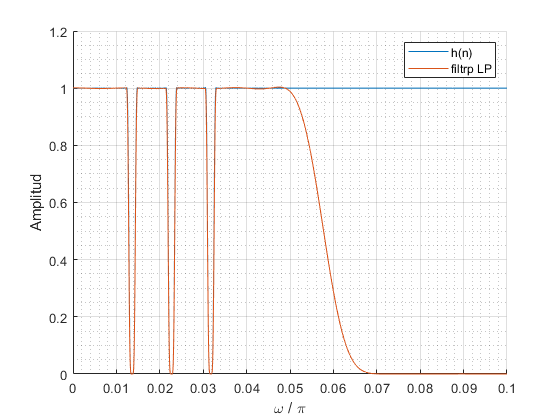

%impulso unicial.
x = [1 zeros(1, 8000)];
%x(n)----->H_lp->K->Hk->K->H_lp------>y(n)

x_lp =  filter(h_lp, 1, x);       %x(n)----->H_lp:
x_lpK = downsample(x_lp , K);     %x(n)----->H_lp->K:
y_ =    filter(h_k, 1, x_lpK );   %x(n)----->H_lp->K->Hk:
y_k =   upsample(y_, K);          %x(n)----->H_lp->K->Hk->K:
y =     filter(h_lp, 1, y_k);     %x(n)-->H_lp->K->Hk->K->H_lp-->y(n)

%filtro original h(n):
y_orig = filter(h,    1, x);

figure()
    hold on
    plot(w/pi, abs(fft(y_orig, nfft)));
    plot(w/pi, K*abs(fft(y, nfft)));
    legend("h(n)", "filtrp LP")
    xlabel("\omega / \pi")
    ylabel("Amplitud")
    grid on;
    grid minor;
    xlim([0 0.1])  

Notar como como ya con el cacnal LP el filtro  optimizado es practicamente el mismo que el original, aunque se puede ver como a altas frecuencias este no es el mismo, por ello hay que sumarlo la parte de altas frecuencias y para ello hay que tener en cuenta el retardo que este canal impone.

**(d) **

**Genere la respuesta total sumando la salida del canal LP con la del HP. Para ello, primero se debe determinar (justificado con cálculos) el retardo adecuado que debe agregarse al canal de altas frecuencias para compensar la diferencia de retardos respecto del canal de bajas. Luego compare las respuestas impulsivas del filtro original con el filtro del sistema completo. **

Para calcular el retardo del canal LP hay que tener en cuenta que para un FIR su retardo será de $N/2$  y que al decimar el $N'=N/k$ pero al sobremuestrear $N' = NxK$ entonces:

    $Retardo_{LP} = \frac{N_{LP}}{2} = \frac{N_{Hlp} + N_{hk}K + N_{Hlp}}{2}$= $\frac{300 + 530K + 300}{2}$ = $4010$

    
$$Retardo_{HP}= \frac{N_{hp}}{2} = \frac{600}{2} = 300$$


por lo que hay que agregarle  un retardo de $3710$y de esa manera los dos canales pueden acoplar correctamente.

Nhlp = length(h_lp) - 1;
Nhk =   length(h_k) - 1;
Nhhp=  length(h_hp) - 1;

RetardoLP = (Nhlp + Nhk*K + Nhlp)/2;
RetardoHP = Nhhp/2;

delay = abs(RetardoLP - RetardoHP)

delay = 3710


y_sum = sum([K*y; ...
             [filter([zeros(1, delay),h_hp], 1, x) zeros(1,7)]   ...
             ]); %completé con zeros al final para corregir el largo.
         

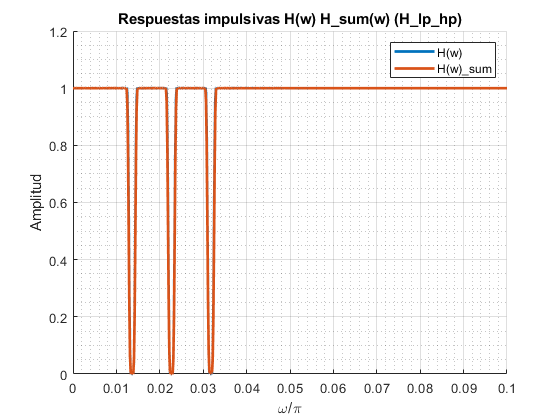

%Comparacion filtro original con el filtro del sistema completo
figure()
    hold on
    plot(w/pi, abs(fft(y_orig, nfft)), 'LineWidth', 2);
    
    plot(w/pi, abs(fft(y_sum, nfft)), 'LineWidth', 2);
    legend("H(w)", "H(w)\_sum")
    xlabel("\omega/\pi")
    ylabel("Amplitud")
    grid on;
    grid minor;
    xlim([0 0.1])
    title("Respuestas impulsivas H(w) H\_sum(w) (H\_lp\_hp)")

Observar cómo al menos visualmente los gráficos son muy similares, esto sugiere que se han hecho bien los ejercicios y el filtro es el adecuado, con la ventaja de un menor orden a diferencia del filtro original, si uno observa con acercamiento se puede ver que incluso los ripples en la banda de paso son menores al original, pero no así en la banda de supresión.

#### Problema 3 

**Si bien la implementación del punto anterior supone una mejora significativa en la eficiencia computacional del filtro, ésta se puede reducir aún más si se implementan las etapas de decimación y expansión mediante una descomposición polifásica.**

**(a) **

**Encuentre las componentes polifásicas de los filtros de decimación e interpolación. Puede utilizar las funciones *****sys=dsp.FIRDecimator(M,h)*****, *****sys=dsp.FIRInterpolator(L,h)***** y***** p=polyphase(sys)***** de Matlab. Si no dispone de estas funciones, puede calcular las componentes polifásicas decimando la respuesta impulsiva del filtro. Luego implemente el conjunto {Hlp(z), ↓ K} de forma eficiente. Haga lo mismo con el conjunto {↑ K, Hlp(z)}. Para verificar si la implementación es correcta en cada caso, compare las respuestas impulsivas de cada conjunto (con y sin descomposición polifásica).**

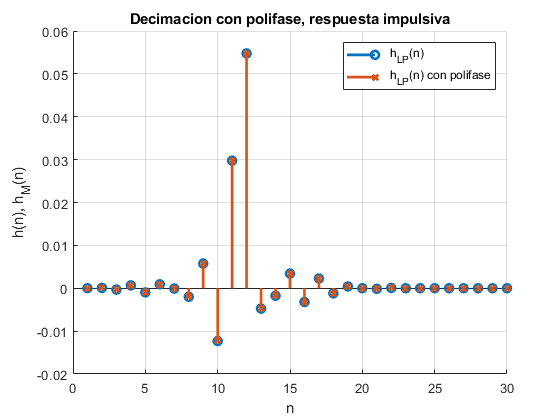

%Decimacion
M = K;


%Para figura 1:
v = conv(h_lp,x);
y1 = downsample(v, M);

y2 = DescPolifaseDecimacion(M, h_lp, x);
Y = fft(y2, nfft);

figure()
    hold on
    stem(1:length(y1), y1, '-o', 'LineWidth', 2)
    stem(1:length(y2), y2, '-x','LineWidth', 2)
    grid on
    legend("h_{LP}(n)", "h_{LP}(n) con polifase")
    xlabel("n")
    ylabel("h(n), h_M(n)")
    title("Decimacion con polifase, respuesta impulsiva")
    xlim([0 30])

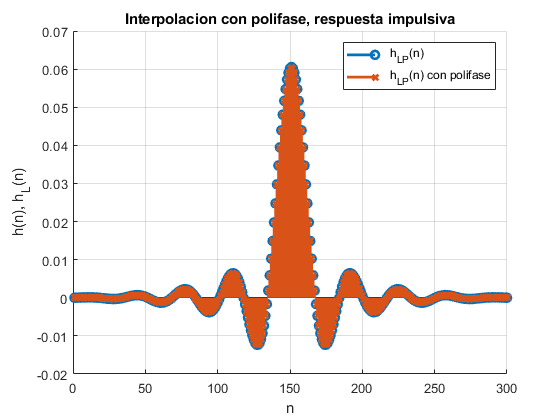

%%Interpolacion
L = K;
  
%aplicando el filtro sin polifase
y3 = filter(h_lp, 1, upsample(x, L));

y4 = DescPolifaseExpancion(L, h_lp, x);
Y4 = fft(y3, nfft);

figure()
    hold on
    stem(1:length(y3), y3, '-o', 'LineWidth', 2)
    stem(1:length(y4), y4, '-x','LineWidth', 2)
    grid on
    legend("h_{LP}(n)", "h_{LP}(n) con polifase")
    xlabel("n")
    ylabel("h(n), h_L(n)")
    title("Interpolacion con polifase, respuesta impulsiva")
    xlim([0 300])    

Se puede observar como las respuestas impulsivas son idénticas entre si con respecto a la original, pero con la diferencias de que con descomposición polifásica el filtro es más eficiente que antes.

(**b)**

**Implemente el canal pasa bajos con la descomposición polifásica de cada etapa y complete el sistema combinando el canal de bajas con el de altas. Nuevamente, calcule el retardo necesario que debe agregarse en el canal de altas para compensar la diferencia y grafique la respuesta en frecuencia del sistema completo comparado con el del Problema 2.**

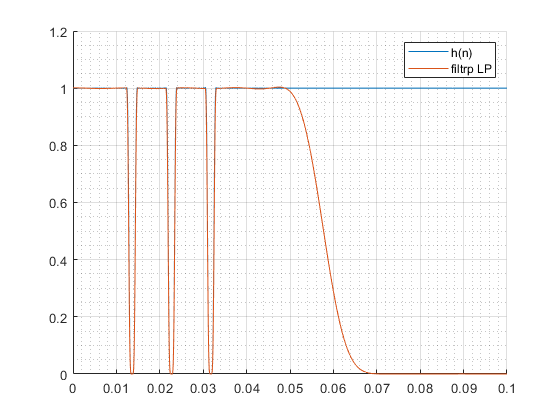

%impulso unicial.
x = [1 zeros(1, 8000)];
%x(n)----->(H_lp->K)*->Hk->(K->H_lp)*------>y(n)
%x(n)----->poli_M-->Hk-->Poli_L------>y(n)

x_lpK = DescPolifaseDecimacion(M, h_lp, x);  %x(n)----->(H_lp->K)*
y_ =    filter(h_k, 1, x_lpK );              %x(n)----->poli_M-->Hk:
y = DescPolifaseExpancion(L, h_lp, y_);      %x(n)->(H_lp->K)*->Hk->(K->H_lp)*->y(n)

%filtro original h(n):
y_orig = filter(h,    1, x);

figure()
    hold on
    plot(w/pi, abs(fft(y_orig, nfft)));
    plot(w/pi, K*abs(fft(y, nfft)));
    legend("h(n)", "filtrp LP")
    grid on;
    grid minor;
    xlim([0 0.1])

Ahora queda saber cual es el retardo que agrega el nuevo filtro LP hecho con polifase pero resulta serel mismo retardo para ambos, debido a que la descomposicion polifase no cambia el orden.

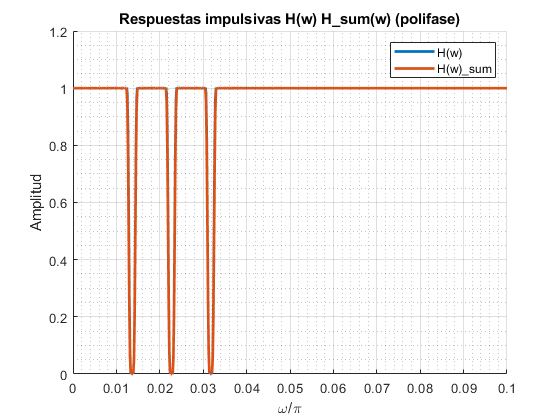

y_hpDelay = filter([zeros(1, delay), h_hp], 1, x);
dt_up =  abs( length(y) - length(y_hpDelay) );

y_sum = sum([  K*y; ...
               [y_hpDelay zeros(1, dt_up)]...
             ]); %completé con zeros al final para corregir el largo.
         

%Comparacion filtro original con el filtro del sistema completo
figure()
    hold on
    plot(w/pi, abs(fft(y_orig, nfft)), 'LineWidth', 2);
    
    plot(w/pi, abs(fft(y_sum, nfft)), 'LineWidth', 2);
    legend("H(w)", "H(w)\_sum")
    xlabel("\omega/\pi")
    ylabel("Amplitud")
    grid on;
    grid minor;
    xlim([0 0.1])
    title("Respuestas impulsivas H(w) H\_sum(w) (polifase)")

Nuevamente se logro lo mismo que en el problema 2 solo que mejorando aun mas la eficiencia computacional.

#### Problema 4 

**En los tres problemas anteriores se propusieron diferentes implementaciones del mismo filtro. Como medida del desempeño computacional, calcule la cantidad de multiplicaciones por segundo (#mult/s), que se necesitarían para cada una de las tres implementaciones (deben tenerse en cuenta todos los filtros utilizados en cada implementación) y compárelas mediante un gráfico de barras. Tome como referencia la realización directa-I como estructura para la implementación de cualquiera de los filtros involucrados (en el Apéndice puede verse esta estructura).**

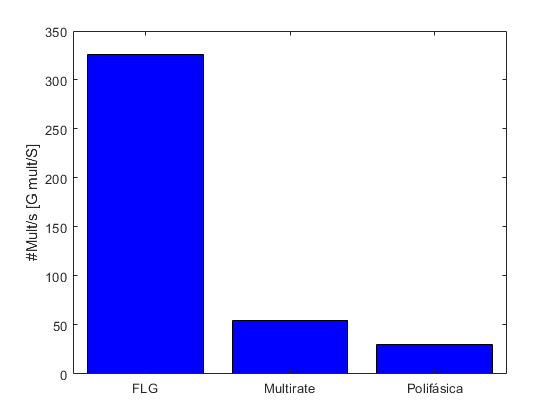

N =   length(h);      % Largo del filtro original(tren de notchs)
N_k =   Nhk + 1;      %Largo del filtro h_k 
N_lp = Nhlp + 1;      %Largo del filtro pasa bajos
N_hp = Nhhp + 1;      %Largo del filtro pasa altos


tipo = categorical({'FLG','Multirate','Polifásica'});
mult = [N*fs,...               %mult    iplicaciones filtro original
    ((N_lp + N_k/K + N_lp)  +  N_hp) * fs,... %
    ((N_lp/K + N_k/K + N_lp/K) + N_hp) * fs];

figure()
bar(tipo, mult*1e-6, 'b')
ylabel('#Mult/s [G mult/S]')

Se puede ver la gran diferencias entre las multiplicaciones necesarias que hay que hacer para cada metodo siendo la polifasica el metodo mas eficiente ~6veces menor  que el FLG, y luego le sigue el metodo multirrate puro, que es 10 veces menor respecto al FLG.

## CONCLUSIONES

Se pudieron comparar los distintos métodos de optimización con respecto al método tradicional de diseño de filtro FLG, por supuesto un filtro más eficiente requiere un mayor trabajo del lado del diseñador del filtro, pero hay casos en donde una mayor eficiencia en el filtro es obligatoria.

Entonces comparando los distintos métodos el de multirrate es bastante más eficiente y agregando polifásica es apenas un poco mas eficiente casi la mitad menos de multiplicaciones necesarias.

Además, hay que tener en cuenta que según los órdenes que se eligen el filtro LS puede no converger, y los retardo para hacer el acople de los dos canales pueden ser muy engorrosos porque hay que agregar algunos ceros al final para completar las dimensiones.

function [] = plotSpectogram(s, x, xh, Fs)
%s = spectrogram(x,window,noverlap,nfft) 
% utiliza puntos de muestreo nfft para calcular la transformada discreta de Fourier.
    window = hann(1000);
    noverlap = 100;
    
    figure()
    subplot(2,2,1)
        spectrogram(s, window, noverlap, [], Fs, 'yaxis')
        title("Señal")
        ylim([0, 2.5])
    subplot(2,2,3)
        spectrogram(x, window, noverlap, [], Fs, 'yaxis')
        title("Señal con ruido")
        ylim([0, 2.5])
    subplot(2,2,[2,4])
        spectrogram(xh, window, noverlap, [], Fs, 'yaxis')
        title("Señal con ruido filtrada")
        ylim([0, 2.5])
        
end

function [W, A, R]= paramLS(Dw, Dws, deltaP, deltaS, w)
    %DeltaW(Dw) ancho de banda de transicion y DeltaS(Ds) ancho de banda de supresion
    %para cada frecuencia w.
    Dw = abs(Dw);
    Dws = abs(Dws);
    n_frec = length(w);
    W = 0;
    A = 1;
    R = [];
    for i = 1:n_frec      
        w_bs = w(i) - Dws(i)/2;     %2
        w_bp = w_bs - Dw(i);        %1
        w_as = w(i) + Dws(i)/2;     %3
        w_ap = w_as + Dw(i);        %4    
        
        W = [W, [w_bp, [w_bs, w_as], w_ap]];
        A = [A, [ 1     0       0     1]];
        R = [R, [deltaP, deltaS]];
    end
    A(end+1) = 1;
    R = [R, deltaP];
    W(1,end+1) = pi;
    %W tiene que ir entre cero y 1.
    W= W./pi; 
        
end


function [h_L]= DescPolifaseExpancion(L, h_lp, x)
    %%Interpolacion:
    
    %Genero las pilifase.
    sysL= dsp.FIRInterpolator(L, h_lp);
    pk = polyphase(sysL);

    %Aplicando el filtro con polifase
    %pk late.
    %[x]-->[P0]
    %[x]-->[P1]        }xp
    %[x]-->[P2]
    xp = zeros(L, length(x)); % por lo general length(x1) > length(pk)
    for i= 1:L
        xp(i, 1:length(x)) = filter(pk(i,:), 1, x);
    end
    
    %Obtengo los pk interpolados de a L=L.
    yk = zeros(L, length(x)*L - 1);
    for i = 1:L
        %[xp]-->[Pi(z)] --> [/|\ L]
        yk_aux = upsample(xp(i,:), L);
        %[xp]-->[Pi(z)] --> [/|\ L] --> [z^-1]
        yk_aux = [zeros(1, i-1), yk_aux];
        %Se lo asigno a la matris yk
        yk(i, 1:length(yk_aux)) = yk_aux;
    end
    
    %Sumo cada componente
    h_L = sum(yk);

end

function [h_L] = DescPolifaseDecimacion(M, h_lp, x)

    %Decimacion
    sysM =   dsp.FIRDecimator(M, h_lp); 
    pk = polyphase(sysM);
    
    %Para figura 2:
    %pki / i={0, 1, 2...M} . ya lo tengo
    
    %Señal retrasada y decimada:
    yk_D = zeros( M, ceil(length(x')/M + M - 1) );
    %Señal retrasada, decimada y pasada por el filtro:
    %Tener en cuenta que conv([1...N], [1...N]) = [1...(N+N-1)], probar.
                                %yk_DP = zeros(M, length(yk_D) + length(pk) -1);
    length_y_aux = ceil((length(x)+ (M-1))/M);
    yk_DP = zeros(M, length_y_aux + length(pk) -1);
    %Aplico [retraso[z^-1] -> decimacion[\|/ M]-> Poli[pk] ] =h(n)
    
    for i = 1:M
       %retardo [z^-1]
       y_aux = [zeros(1, i-1), x];
       %decimacion[\|/ M]
       y_aux = downsample(y_aux, M);
       %Poli[pk] ] =h(n)
       l_conv = (length(y_aux) + length(pk) -1); %largo de la convolucion
       yk_DP(i,1: l_conv) = conv(y_aux, pk(i,:));
    end
    %Sumo cada componente
    h_L = sum(yk_DP);

end